# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

Forecasts of 2022 are based on the in-sample estimation of 2021.

The difference between "exercise_VolForecastRV20220529.mlx" is that we add HAR model.

clc,clear
addpath("data_Files/")
addpath("m_Files_ClusterPartition/")
addpath("m_Files_GARCHfamily/")
addpath("m_Files_Color/colormap/");
addpath("results_Files/");

## SP500

estimation window = 1000

Time: 

Results: 

datatable=readtable("SP500_0608.xlsx");
name='SP500';
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
K_GARCH=zeros(n,1);
K_EGARCH=zeros(n,1);
K_GJRGARCH=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);

i1=0;I=find(oos_index==1);
for i=I(1):I(end)
    i1=i1+1
    index=i-1000:i-1;
    %rv=datatable.RV(index);

HAR

    Jump=zeros(size(datatable.RV(index)));
        index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
        Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [LB,J,~]=Fisher_div_sqr(v_HAR,5);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [~,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,datatable.RV(index),v_HAR,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

GARCH

    ret=datatable.Return(index);
    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    [LB,J,~]=Fisher_div_sqr(v_GARCH,5);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

EGARCH

    Mdl=egarch('GARCH',NaN,'ARCH',NaN,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_EGARCH = infer(EstMdl,ret);
    vf_EGARCH(i1)=forecast(EstMdl,1,ret);

    [LB,J,~]=Fisher_div_sqr(v_EGARCH,5);
    K = OptimalClusterNumber(v_EGARCH,LB);
    K_EGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_EGARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPEGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_EGARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPEGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJRGARCH = infer(EstMdl,ret);
    vf_GJRGARCH(i1)=forecast(EstMdl,1,ret);

    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    K_GJRGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GJRGARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

RSGARCH

    addpath("m_Files_swgarch")
    estimation = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;

    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,5);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    estimation = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;

    [~,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH);
    estimation = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;

    rmpath("m_Files_swgarch")
end

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

forecast_table=table(Timeline_outsample,datatable.Return(I),rv,vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_EGARCH,vf_CPEGARCH,vf_CPEGARCHiteration,vf_GJRGARCH,vf_CPGJRGARCH,vf_CPGJRGARCHiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration,vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    'VariableNames',{'Date','Return','RV','GARCH','CPGARCH','GARCH_Ite','EGARCH', ...
    'CPEGARCH','CPEGARCH_Ite','GJRGARCH','CPGJRGARCH','CPGJRGARCH_Ite', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH_Ite','HAR','CPHAR','HAR_Ite'});

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

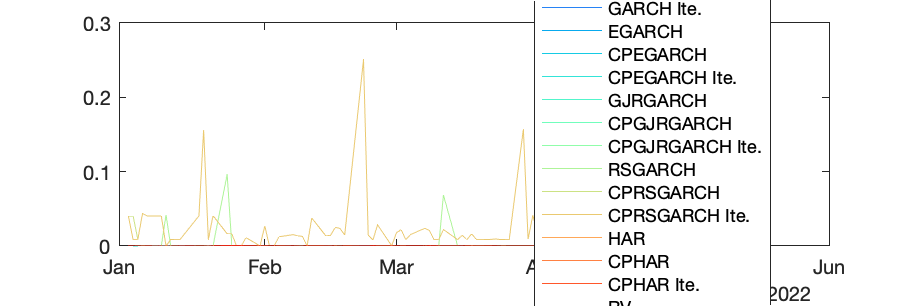

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(16);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_EGARCH, "Color",col(4,:));
plot(Timeline_outsample,vf_CPEGARCH, "Color",col(5,:))
plot(Timeline_outsample,vf_CPEGARCHiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_GJRGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPGJRGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPGJRGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(10,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(11,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(12,:))
plot(Timeline_outsample,vf_HAR, "Color",col(13,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(14,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(15,:))
plot(Timeline_outsample,rv, "Color",col(16,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");
set(gcf,'Position',[500 500 900 300]);

Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

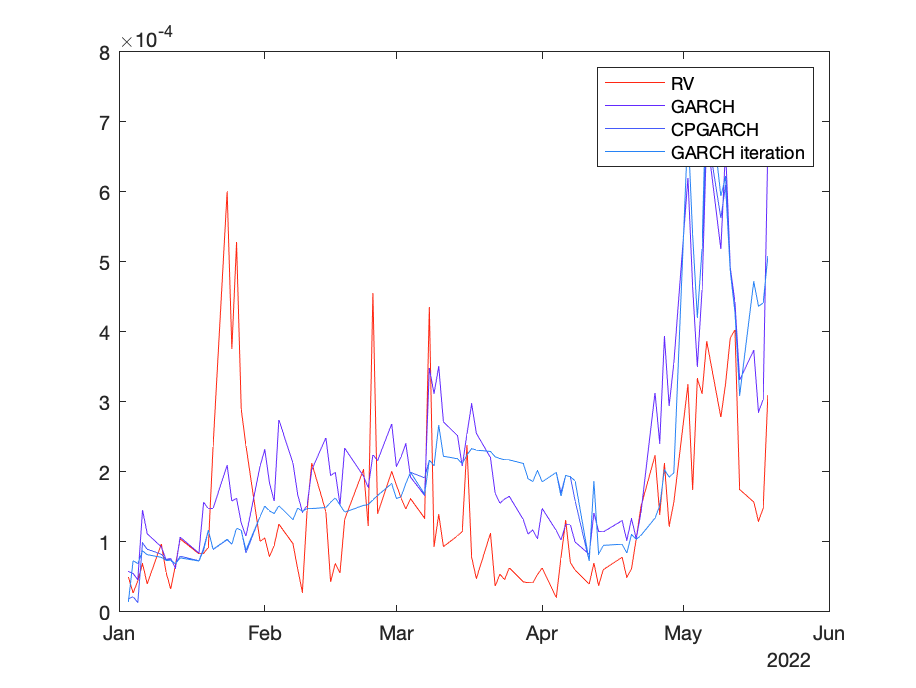

figure;
plot(Timeline_outsample,rv, "Color",col(16,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of optimal cluster number in each estimation window

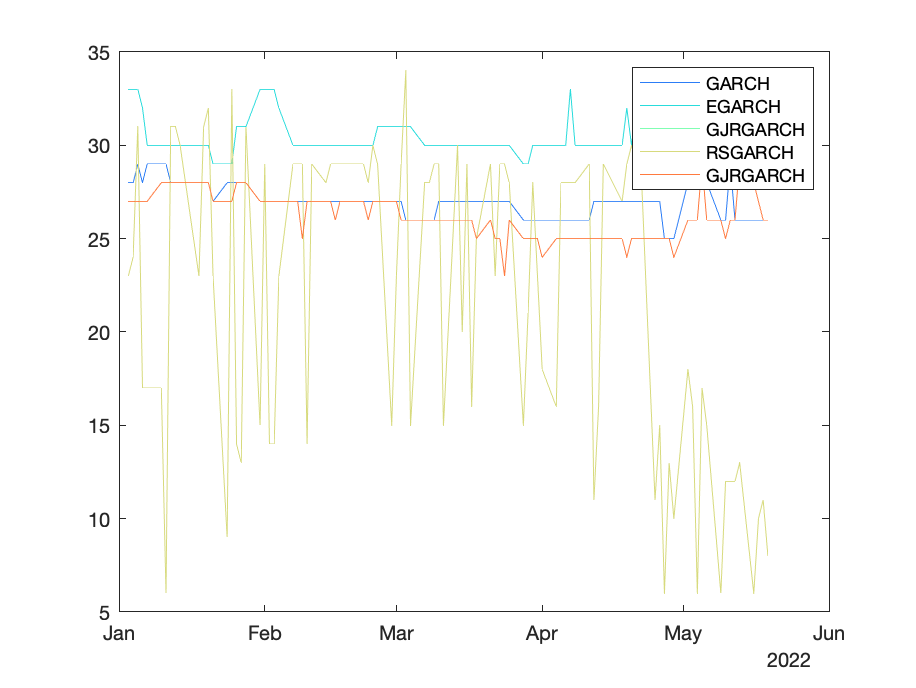

figure;
col=rainbow(5);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_EGARCH,"Color",col(2,:));hold on
plot(Timeline_outsample,K_GJRGARCH,"Color",col(3,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(4,:));
plot(Timeline_outsample,K_GJRGARCH,"Color",col(5,:));
legend("GARCH","EGARCH","GJRGARCH","RSGARCH","GJRGARCH")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 15×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00010858    0.00013997
    CPGARCH            0.00010897    0.00015064
    GARCH Ite.         0.00011047    0.00015361
    EGARCH             0.00010858    0.00013633
    CPEGARCH           0.00016855     0.0002302
    CPEGARCH Ite.      0.00014467    0.00020094
    GJRGARCH           0.00012698    0.00017229
    CPGJRGARCH         0.00010689    0.00016162
    CPGJRGARCH Ite.    0.00010713    0.00016482
    RSGARCH              0.021358       0.05297
    CPRSGARCH             0.02094        0.0389
    CPRSGARCH Ite.        0.02058      0.038678
    HAR              

#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_EGARCH-rv));mean(abs(vf_CPEGARCH-rv));mean(abs(vf_CPEGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_EGARCH-rv).^2);mean((vf_CPEGARCH-rv).^2);mean((vf_CPEGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 12×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00010858    0.00013997
    CPGARCH            0.00010897    0.00015064
    GARCH Ite.         0.00011047    0.00015361
    EGARCH             0.00010858    0.00013633
    CPEGARCH           0.00016855     0.0002302
    CPEGARCH Ite.      0.00014467    0.00020094
    GJRGARCH           0.00012698    0.00017229
    CPGJRGARCH         0.00010689    0.00016162
    CPGJRGARCH Ite.    0.00010713    0.00016482
    HAR                6.7487e-05    0.00010759
    CPHAR              6.8429e-05    0.00010774
    HAR Ite.           6.7645e-05    0.00010617


DM test


table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 11×1 table
                          Var1   
                       __________

    CPGARCH              0.093661
    GARCH Ite.            0.05087
    GJRGARCH            0.0035786
    CPGJRGARCH            0.19113
    CPGJRGARCH Ite.       0.15789
    RSGARCH            0.00081058
    CPRSGARCH            0.019841
    CPRSGARCH Ite.        0.02102
    HAR                   0.99781
    CPHAR                 0.99543
    HAR Ite.               0.9968


#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_EGARCH,~,~,stats_EGARCH]=regress(rv,[ones(size(rv)) vf_EGARCH]);
[~,bint_CPEGARCH,~,~,stats_CPEGARCH]=regress(rv,[ones(size(rv)) vf_CPEGARCH]);
[~,bint_CPEGARCHiteration,~,~,stats_CPEGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPEGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_EGARCH(end,1);bint_CPEGARCH(end,1);bint_CPEGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_EGARCH(end,2);bint_CPEGARCH(end,2);bint_CPEGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_EGARCH(1);stats_CPEGARCH(1);stats_CPEGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.','EGARCH', ...
    'CPEGARCH','CPEGARCH Ite.','GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 15×3 table
                       low_bound     upper_bound       R2    
                       __________    ___________    _________

    GARCH                 0.35189       0.64519       0.32645
    CPGARCH               0.20966       0.51985       0.18829
    GARCH Ite.            0.20408       0.50689       0.18778
    EGARCH                0.45531       0.72376       0.44722
    CPEGARCH            -0.053399       0.19653      0.013568
    CPEGARCH Ite.       0.0089975       0.27596      0.045605
    GJRGARCH              0.31243       0.52771       0.38978
    CPGJRGARCH            0.11794       0.44368       0.11085
    CPGJRGARCH Ite.      0.077947       0.40842      0.083276
    RSGARCH            0.000

#### Figure of volatility persistence

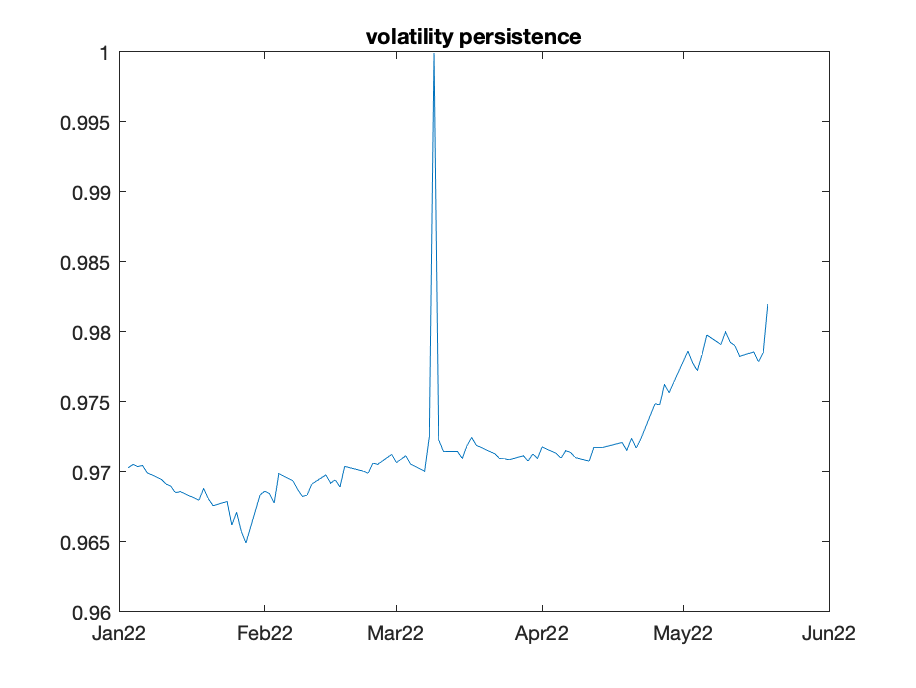

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size1000_20220613'),"vol_persis", ...
    "forecast_table","K_GARCH","K_EGARCH","K_GJRGARCH","K_RSGARCH","K_HAR");


## DAX

estimation window = 1000

Time: 

Results: 

datatable=readtable("DAX_0608.xlsx");
name='DAX';
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
K_GARCH=zeros(n,1);
K_EGARCH=zeros(n,1);
K_GJRGARCH=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);

i1=0;I=find(oos_index==1);
for i=I(1):I(end)
    i1=i1+1
    index=i-1000:i-1;

HAR

    Jump=zeros(size(datatable.RV(index)));
        index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
        Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [LB,J,~]=Fisher_div_sqr(v_HAR,5);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [~,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

GARCH

    ret=datatable.Return(index);
    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    [LB,J,~]=Fisher_div_sqr(v_GARCH,5);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJRGARCH = infer(EstMdl,ret);
    vf_GJRGARCH(i1)=forecast(EstMdl,1,ret);

    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    K_GJRGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GJRGARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

RSGARCH

    addpath("m_Files_swgarch")
    [estimation,probabilities] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;

    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,5);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;

    [~,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;

    rmpath("m_Files_swgarch")
end

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

Unrecognized function or variable 'Timeline_outsample'.

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration


Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJRGARCH, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJRGARCH, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRGARCHiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");

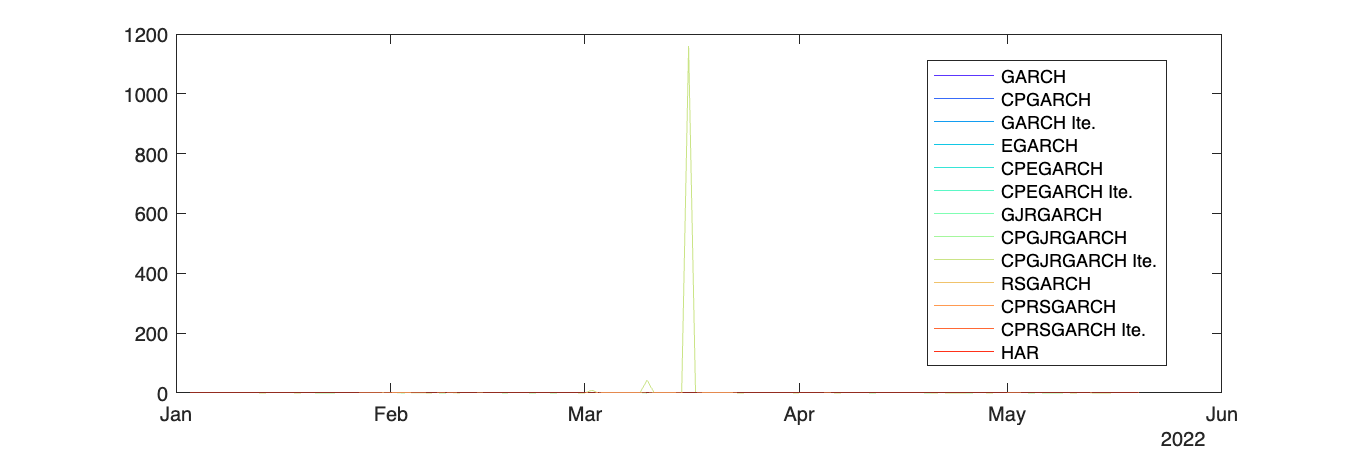

set(gcf,'Position',[500 500 900 300]);

Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

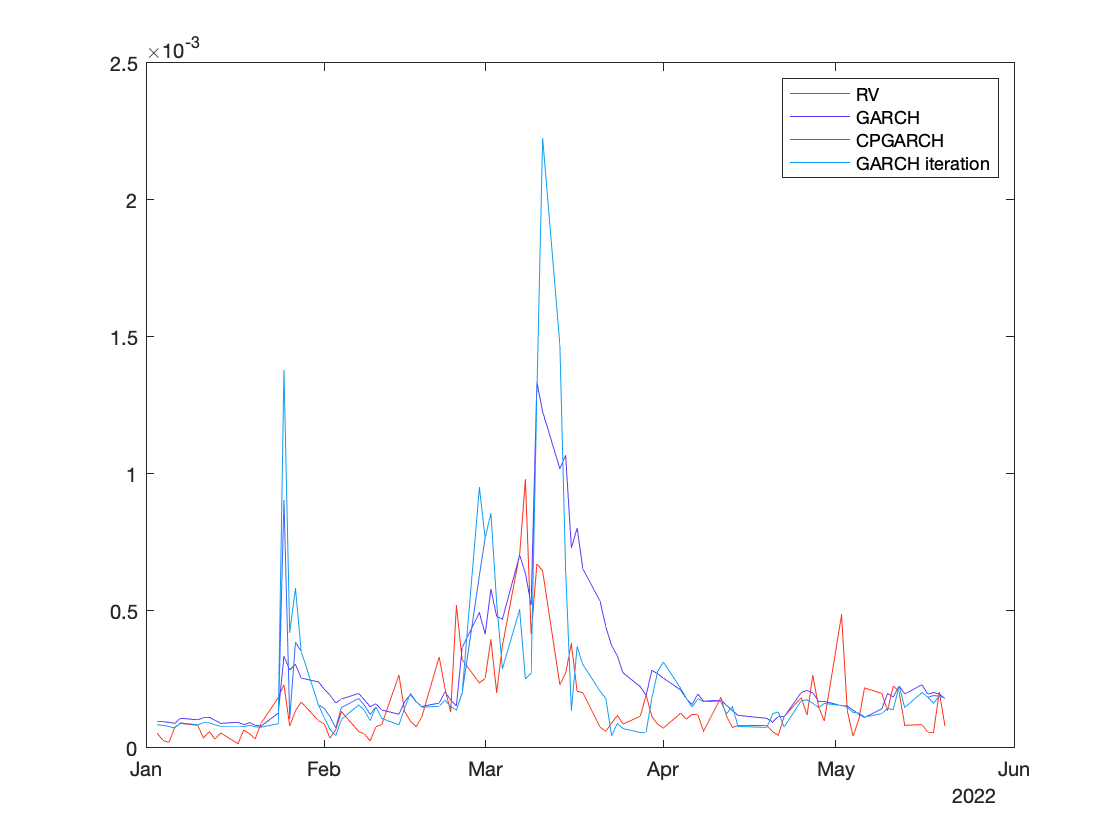

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of optimal cluster number in each estimation window

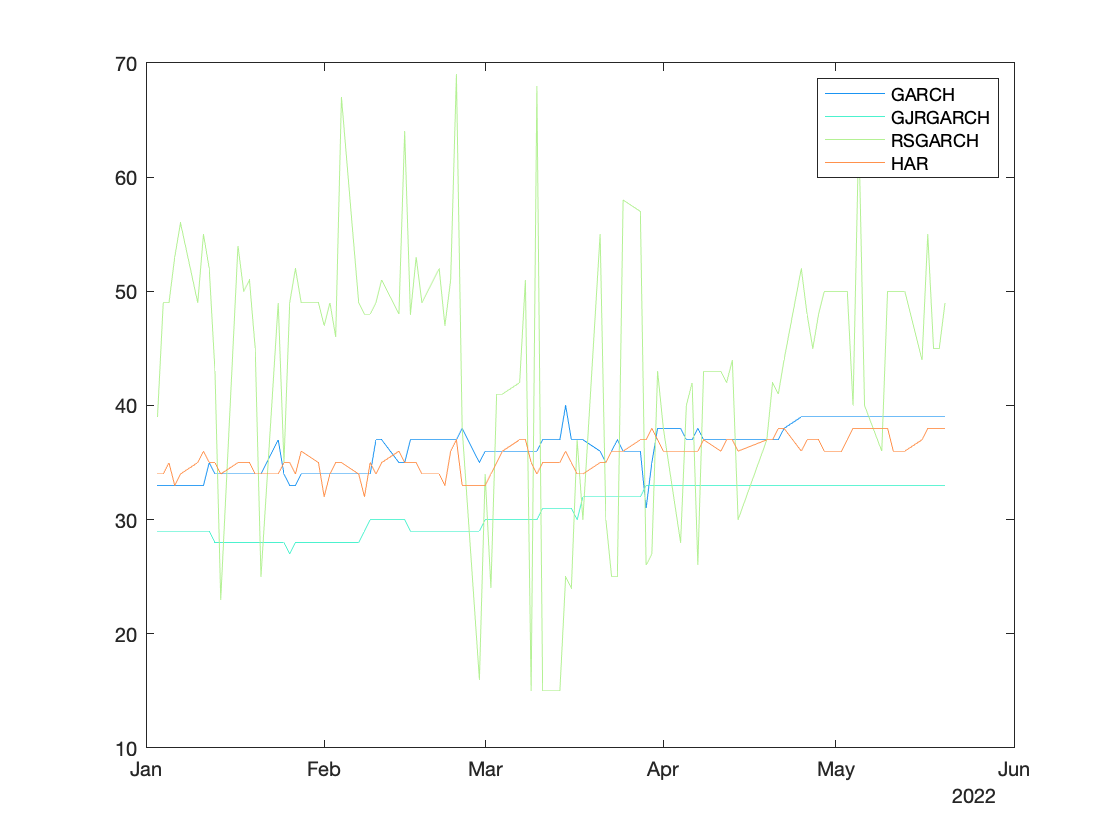

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJRGARCH,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00013854    0.00021283
    CPGARCH            0.00014216      0.000273
    GARCH Ite.           0.000154    0.00029884
    GJRGARCH           0.00012513    0.00017121
    CPGJRGARCH         0.00016892    0.00033783
    CPGJRGARCH Ite.    0.00016775    0.00032835
    RSGARCH            0.00012258    0.00019806
    CPRSGARCH               12.16        116.98
    CPRSGARCH Ite.         12.693        117.06
    HAR                8.4255e-05    0.00013449
    CPHAR              7.6774e-05    0.00011898
    HAR Ite.           7.7734e-05    0.00012055


#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 9×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00013854    0.00021283
    CPGARCH            0.00014216      0.000273
    GARCH Ite.           0.000154    0.00029884
    GJRGARCH           0.00012513    0.00017121
    CPGJRGARCH         0.00016892    0.00033783
    CPGJRGARCH Ite.    0.00016775    0.00032835
    HAR                8.4255e-05    0.00013449
    CPHAR              7.6774e-05    0.00011898
    HAR Ite.           7.7734e-05    0.00012055


DM test


table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 11×1 table
                         Var1  
                       ________

    CPGARCH              0.1288
    GARCH Ite.         0.064283
    GJRGARCH            0.93715
    CPGJRGARCH         0.023828
    CPGJRGARCH Ite.    0.025098
    RSGARCH             0.71773
    CPRSGARCH           0.15863
    CPRSGARCH Ite.      0.15829
    HAR                 0.99316
    CPHAR               0.99856
    HAR Ite.            0.99836


#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×3 table
                        low_bound     upper_bound       R2   
                       ___________    ___________    ________

    GARCH                  0.32056       0.52724       0.4085
    CPGARCH                0.17824       0.35912      0.26591
    GARCH Ite.             0.15242       0.32413       0.2402
    GJRGARCH               0.47507       0.65457      0.61913
    CPGJRGARCH             0.17043       0.30743      0.33307
    CPGJRGARCH Ite.        0.17804       0.31709      0.34227
    RSGARCH                0.30311       0.53726      0.34583
    CPRSGARCH          -8.3191e-08    4.6967e-07     0.019662
    CPRSGARCH Ite.     -6.6881e-08    4.8491e-07     0.023014
    HAR                    0

#### Figure of volatility persistence

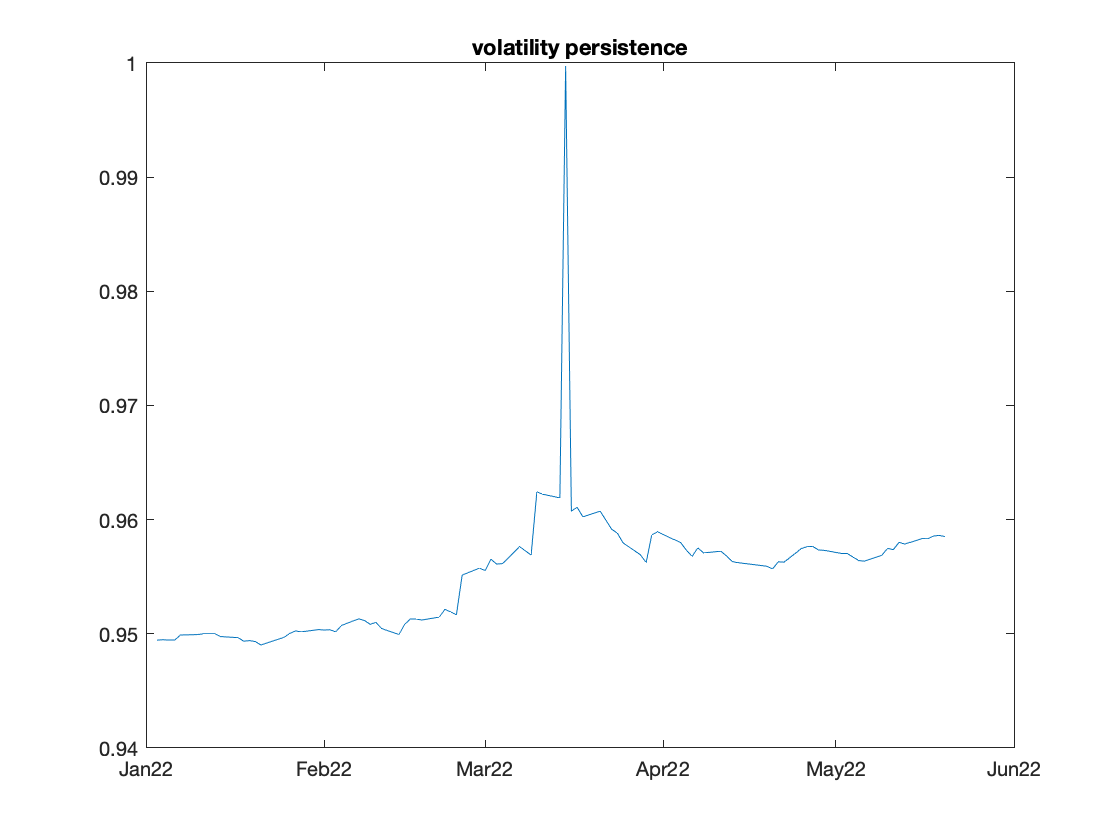

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size1000_20220613'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJRGARCH","vf_CPGJRGARCH","vf_CPGJRGARCHiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJRGARCH","K_RSGARCH","K_HAR");

## FTSE

estimation window = 1000

Time: 

Results: 

datatable=readtable("FTSE_0608.xlsx");
name='FTSE';
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
K_GARCH=zeros(n,1);
K_EGARCH=zeros(n,1);
K_GJRGARCH=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);

i1=0;I=find(oos_index==1);
for i=I(1):I(end)
    i1=i1+1
    index=i-1000:i-1;

HAR

    Jump=zeros(size(datatable.RV(index)));
        index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
        Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [LB,J,~]=Fisher_div_sqr(v_HAR,5);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [~,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

GARCH

    ret=datatable.Return(index);
    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    [LB,J,~]=Fisher_div_sqr(v_GARCH,5);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJRGARCH = infer(EstMdl,ret);
    vf_GJRGARCH(i1)=forecast(EstMdl,1,ret);

    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    K_GJRGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GJRGARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

RSGARCH

    addpath("m_Files_swgarch")
    [estimation,probabilities] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;

    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,5);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;

    [~,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;

    rmpath("m_Files_swgarch")
end

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJRGARCH, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJRGARCH, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRGARCHiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");

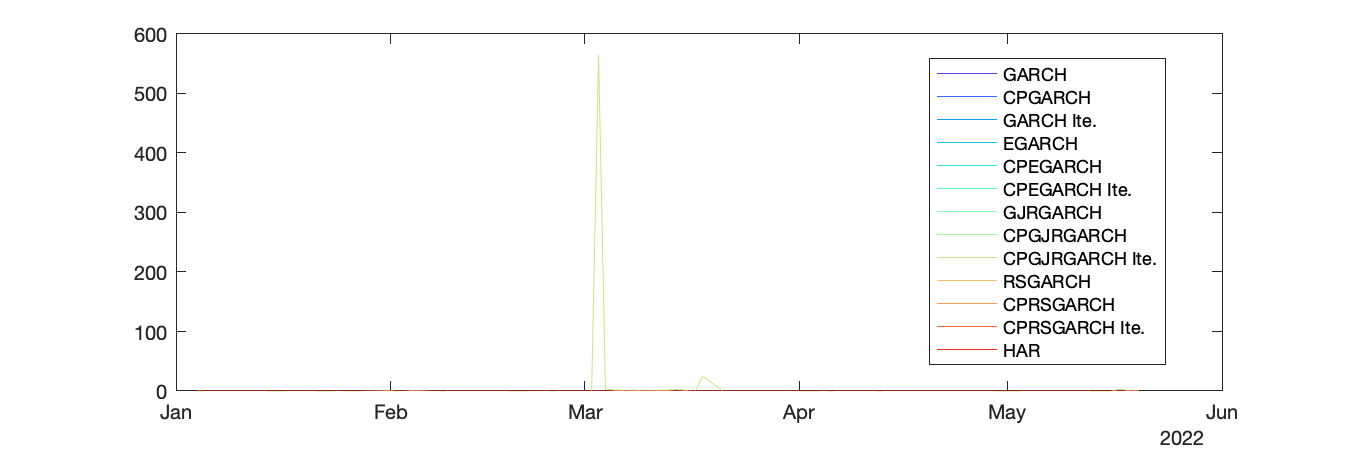

set(gcf,'Position',[500 500 900 300]);

Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

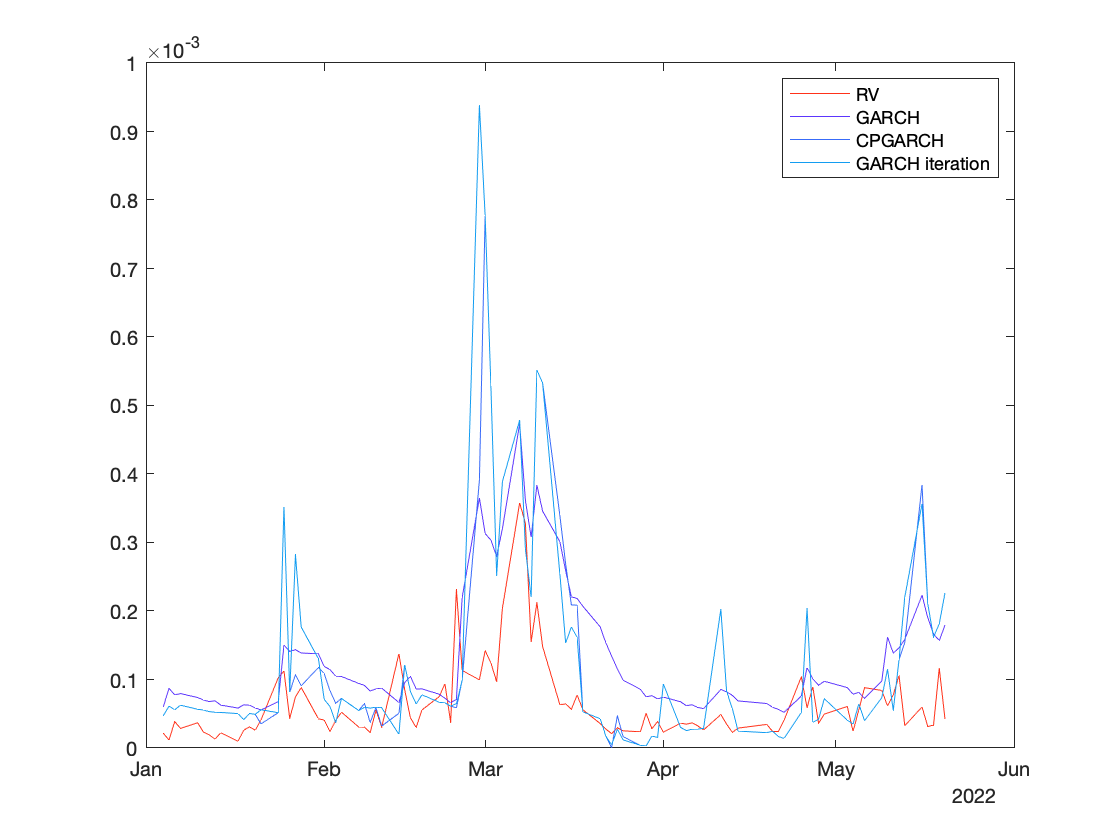

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of optimal cluster number in each estimation window

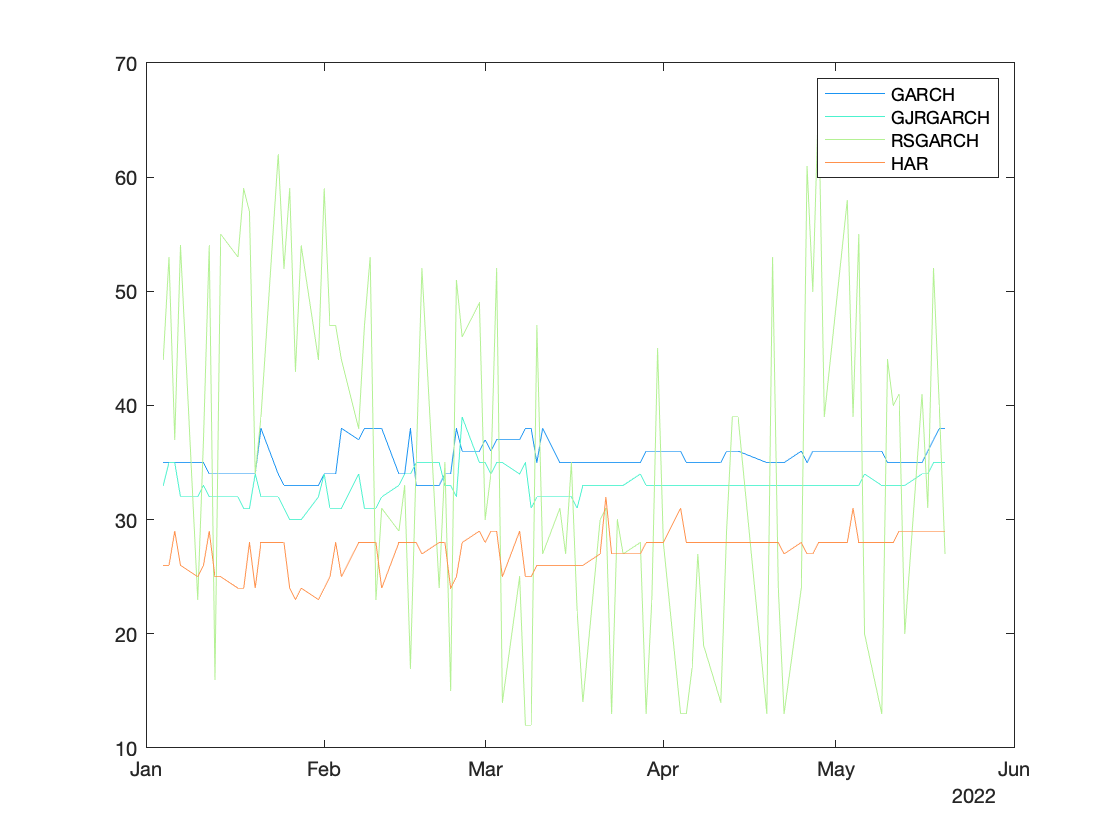

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJRGARCH,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              7.3456e-05    9.2276e-05
    CPGARCH            7.2508e-05     0.0001277
    GARCH Ite.         7.8317e-05     0.0001495
    GJRGARCH           6.8729e-05    8.4441e-05
    CPGJRGARCH         7.9454e-05    0.00016264
    CPGJRGARCH Ite.    8.5146e-05    0.00016408
    RSGARCH            8.4667e-05    0.00010646
    CPRSGARCH              6.2978        57.598
    CPRSGARCH Ite.         6.3606          57.6
    HAR                 2.938e-05    4.8495e-05
    CPHAR              2.7064e-05    4.3214e-05
    HAR Ite.           2.7146e-05    4.3323e-05


#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 9×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              7.3456e-05    9.2276e-05
    CPGARCH            7.2508e-05     0.0001277
    GARCH Ite.         7.8317e-05     0.0001495
    GJRGARCH           6.8729e-05    8.4441e-05
    CPGJRGARCH         7.9454e-05    0.00016264
    CPGJRGARCH Ite.    8.5146e-05    0.00016408
    HAR                 2.938e-05    4.8495e-05
    CPHAR              2.7064e-05    4.3214e-05
    HAR Ite.           2.7146e-05    4.3323e-05


DM test


table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 11×1 table
                         Var1  
                       ________

    CPGARCH             0.04151
    GARCH Ite.         0.040486
    GJRGARCH            0.97517
    CPGJRGARCH         0.018764
    CPGJRGARCH Ite.    0.014261
    RSGARCH            0.012348
    CPRSGARCH           0.15816
    CPRSGARCH Ite.      0.15815
    HAR                       1
    CPHAR                     1
    HAR Ite.                  1


#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×3 table
                        low_bound     upper_bound       R2    
                       ___________    ___________    _________

    GARCH                   0.3697       0.56363       0.49273
    CPGARCH                0.18762       0.32494       0.36881
    GARCH Ite.             0.14321       0.26949       0.30934
    GJRGARCH               0.42347       0.62177       0.53816
    CPGJRGARCH             0.14903       0.25435       0.38087
    CPGJRGARCH Ite.        0.15798       0.26046       0.41149
    RSGARCH                0.32731       0.49933       0.49202
    CPRSGARCH          -1.5229e-07    2.7325e-07     0.0033769
    CPRSGARCH Ite.     -1.5163e-07    2.7393e-07     0.0034517
    HAR            

#### Figure of volatility persistence

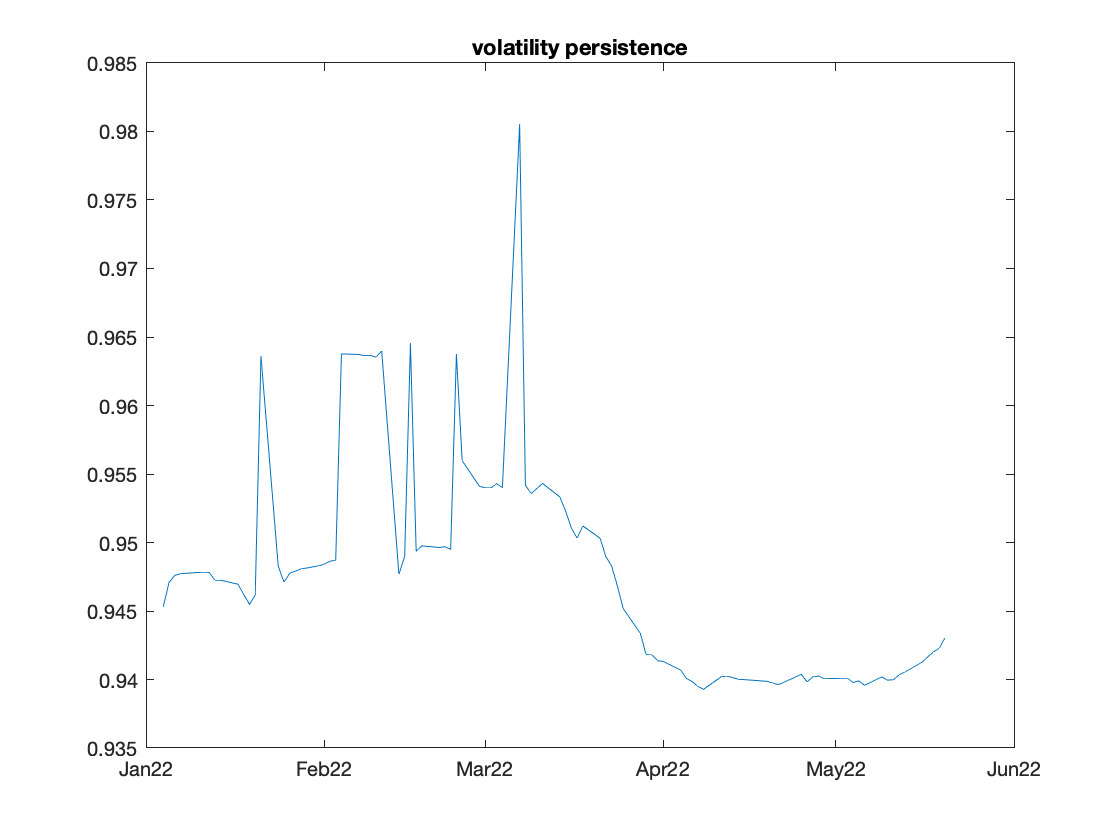

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size1000_20220613'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJRGARCH","vf_CPGJRGARCH","vf_CPGJRGARCHiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJRGARCH","K_RSGARCH","K_HAR");

## NIKKIE

estimation window = 1000

Time: 

Results: 

datatable=readtable("NIKKIE_0608.xlsx");
name='NIKKIE';
oos_index=datatable.Date>=datetime(2022,01,01);
rv=datatable.RV(oos_index);

n=sum(oos_index);
v_residuals=datatable.Return(oos_index).^2;
vf_GARCH=zeros(n,1);
vf_CPGARCH=zeros(n,1);
vf_CPGARCHiteration=zeros(n,1);
vf_EGARCH=zeros(n,1);
vf_CPEGARCH=zeros(n,1);
vf_CPEGARCHiteration=zeros(n,1);
vf_GJRGARCH=zeros(n,1);
vf_CPGJRGARCH=zeros(n,1);
vf_CPGJRGARCHiteration=zeros(n,1);
vf_RSGARCH=zeros(n,1);
vf_CPRSGARCH=zeros(n,1);
vf_CPRSGARCHiteration=zeros(n,1);
vf_HAR=zeros(n,1);
vf_CPHAR=zeros(n,1);
vf_CPHARiteration=zeros(n,1);
vol_persis=zeros(n,1);
K_GARCH=zeros(n,1);
K_EGARCH=zeros(n,1);
K_GJRGARCH=zeros(n,1);
K_RSGARCH=zeros(n,1);
K_HAR=zeros(n,1);

i1=0;I=find(oos_index==1);
for i=I(1):I(end)
    i1=i1+1
    index=i-1000:i-1;

HAR

    Jump=zeros(size(datatable.RV(index)));
        index_Jump=(datatable.RV(index)-datatable.RBP(index))>0;
        Jump(index_Jump) = log(datatable.RV(index_Jump)-datatable.RBP(index_Jump)+1);
    logrv=log(datatable.RV);
    vt=logrv(index);
    vt_1=logrv(index-1);
    vt_5=movmean(logrv,5,'Endpoints','discard');
    vt_5=vt_5(index-5);
    vt_22=movmean(logrv,5,'Endpoints','discard');
    vt_22=vt_22(index-22);
    rt_1=datatable.Return(index-1);
    rvt_1=datatable.RV(index-1);
    a1=abs(rt_1)./sqrt(rvt_1);
    a2=a1;a2(rt_1>0)=0;
    x0=ones(size(vt));
    [v_HAR,paras]=Vol_HAR(vt,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    vf_HAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [LB,J,~]=Fisher_div_sqr(v_HAR,5);
    K = OptimalClusterNumber(v_HAR,LB);
    K_HAR(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_HAR,K,J);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHAR(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

    [~,Nodes] = Vol_ClusterPartitionIterationHAR(Nodes,vt,v_HAR,[vt_1,vt_5,vt_22,Jump,a1,a2]);
    [~,paras]=Vol_HAR(vt(Nodes(end):end),[vt_1(Nodes(end):end),vt_5(Nodes(end):end),vt_22(Nodes(end):end),Jump(Nodes(end):end),a1(Nodes(end):end),a2(Nodes(end):end)]);
    vf_CPHARiteration(i1)=exp([1,vt_1(end),vt_5(end),vt_22(end),Jump(end),a1(end),a2(end)]*paras);

GARCH

    ret=datatable.Return(index);
    Mdl=garch('GARCHLags',1,'ARCHLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GARCH=infer(EstMdl,ret);
    vf_GARCH(i1)=forecast(EstMdl,1,ret);
    vol_persis(i1)=EstMdl.GARCH{1}+EstMdl.ARCH{1};

    [LB,J,~]=Fisher_div_sqr(v_GARCH,5);
    K = OptimalClusterNumber(v_GARCH,LB);
    K_GARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

GJR-GARCH

    Mdl=gjr('GARCHLags',1,'ARCHLags',1,'LeverageLags',1,'Offset',NaN);
    EstMdl = estimate(Mdl,ret,"Display","off");
    v_GJRGARCH = infer(EstMdl,ret);
    vf_GJRGARCH(i1)=forecast(EstMdl,1,ret);

    [LB,J,~]=Fisher_div_sqr(v_GJRGARCH,5);
    K = OptimalClusterNumber(v_GJRGARCH,LB);
    K_GJRGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_GJRGARCH,K,J);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCH(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

    [~,Nodes] = Vol_ClusterPartitionIteration(Nodes,ret,v_GJRGARCH);
    EstMdl = estimate(Mdl,ret(Nodes(end):end),"Display","off");
    vf_CPGJRGARCHiteration(i1)=forecast(EstMdl,1,ret(Nodes(end):end));

RSGARCH

    addpath("m_Files_swgarch")
    [estimation,probabilities] = swgarch(ret, 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    v_RSGARCH=estimation.H(2:end);
    vf_RSGARCH(i1)=datafcst.vH;

    [LB,J,~]=Fisher_div_sqr(v_RSGARCH,5);
    K = OptimalClusterNumber(v_RSGARCH,LB);
    K_RSGARCH(i1)=K;
    [~,Nodes]=Vol_ClusterPartition(v_RSGARCH,K,J);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCH(i1)=datafcst.vH;

    [~,Nodes] = Vol_ClusterPartitionIterationRSGARCH(Nodes,ret,v_RSGARCH);
    [estimation,probabilities] = swgarch(ret(Nodes(end):end), 2, 'NORMAL','HAAS',...
        'CONS', {'YES',[]}, [0.1 0.1 0.82;0.01 0.01 0.5],...
        [0.8 0.2;0.2 0.8],[],[]);
    datafcst = swgarch_forecast(1,2,estimation.garch,...
        estimation.transM,'INDEP','NORMAL',[],0,ret,...
        estimation.H,probabilities);
    vf_CPRSGARCHiteration(i1)=datafcst.vH;

    rmpath("m_Files_swgarch")
end

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

### Results: 

#### Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration, EGARCH, CPEGARCH, CPEGARCH iteration, GJRGARCH, CPGJRGARCH, CPGJRGARCH iteration, RSGARCH, CPRSGARCH, CPRSGARCH iteration, HAR, CPHAR, CPHARiteration

Timeline_outsample=datatable.Date(oos_index);
figure;
col=rainbow(13);
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:));hold on
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
plot(Timeline_outsample,vf_GJRGARCH, "Color",col(4,:));
plot(Timeline_outsample,vf_CPGJRGARCH, "Color",col(5,:))
plot(Timeline_outsample,vf_CPGJRGARCHiteration, "Color",col(6,:))
plot(Timeline_outsample,vf_RSGARCH, "Color",col(7,:));
plot(Timeline_outsample,vf_CPRSGARCH, "Color",col(8,:))
plot(Timeline_outsample,vf_CPRSGARCHiteration, "Color",col(9,:))
plot(Timeline_outsample,vf_HAR, "Color",col(10,:))
plot(Timeline_outsample,vf_CPHAR, "Color",col(11,:))
plot(Timeline_outsample,vf_CPHARiteration, "Color",col(12,:))
plot(Timeline_outsample,rv, "Color",col(13,:))
legend("GARCH","CPGARCH","GARCH Ite.","EGARCH", ...
    "CPEGARCH","CPEGARCH Ite.", "GJRGARCH", "CPGJRGARCH", "CPGJRGARCH Ite.", ...
    "RSGARCH", "CPRSGARCH", "CPRSGARCH Ite.","HAR","CPHAR","CPHAR Ite.","RV","Location","best");

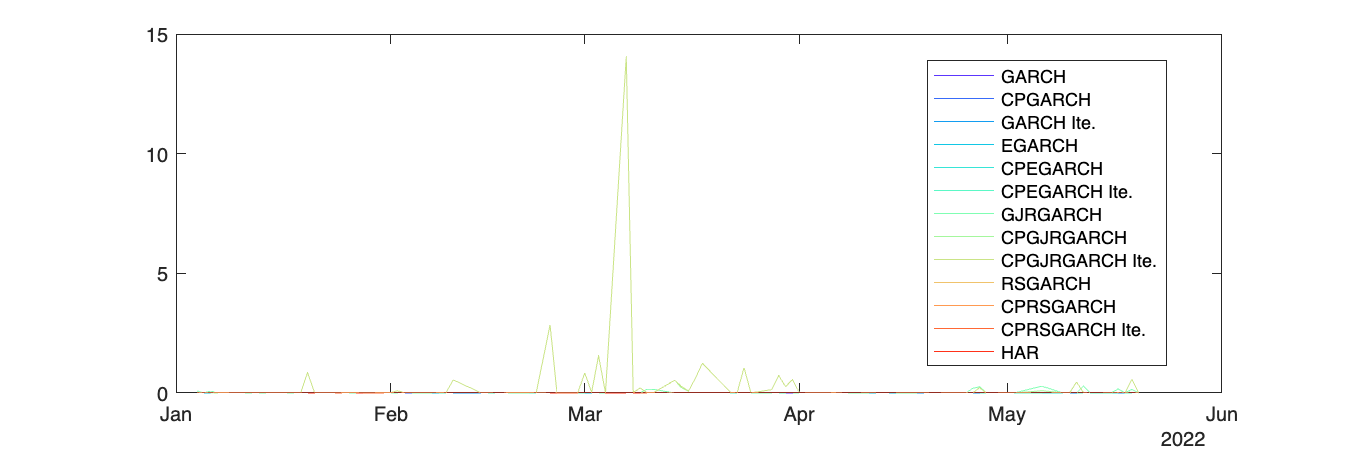

set(gcf,'Position',[500 500 900 300]);

Volatility forecasts: GARCH, CPGARCH, CPGARCH iteration

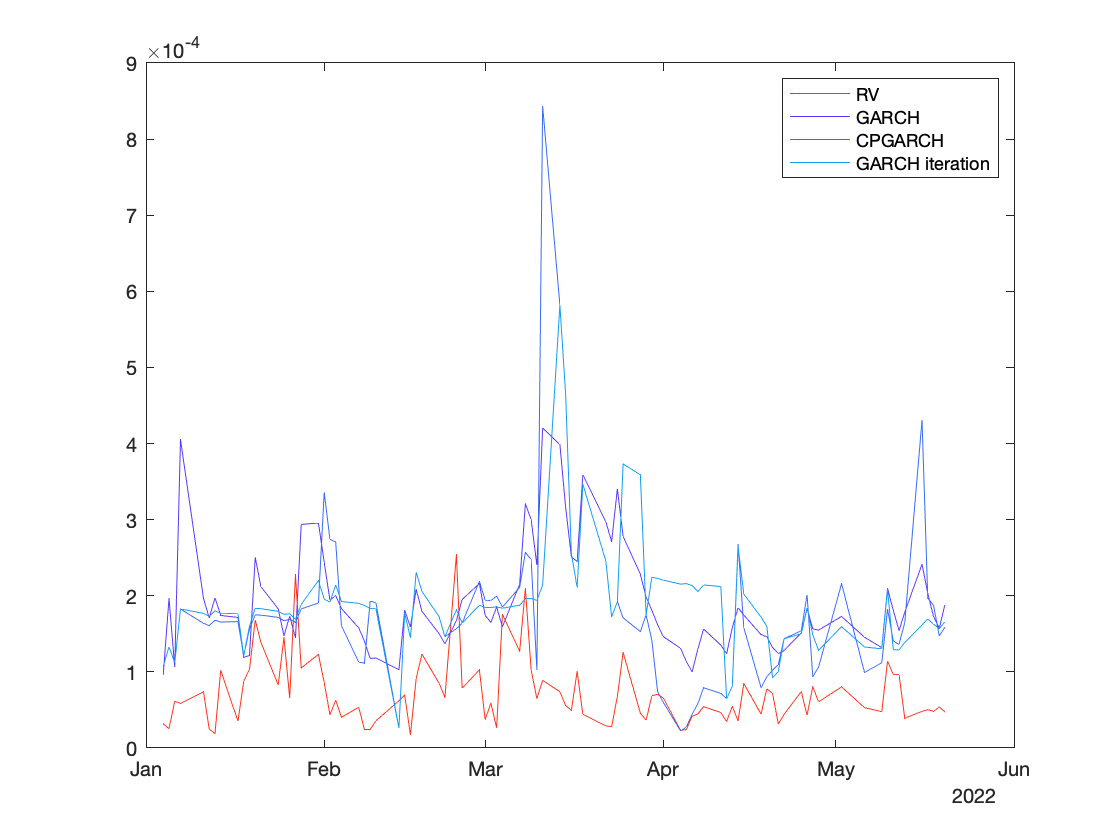

figure;
plot(Timeline_outsample,rv, "Color",col(13,:));hold on
plot(Timeline_outsample,vf_GARCH, "Color",col(1,:))
plot(Timeline_outsample,vf_CPGARCH, "Color",col(2,:))
plot(Timeline_outsample,vf_CPGARCHiteration, "Color",col(3,:))
legend("RV","GARCH","CPGARCH","GARCH iteration");

#### Figure of optimal cluster number in each estimation window

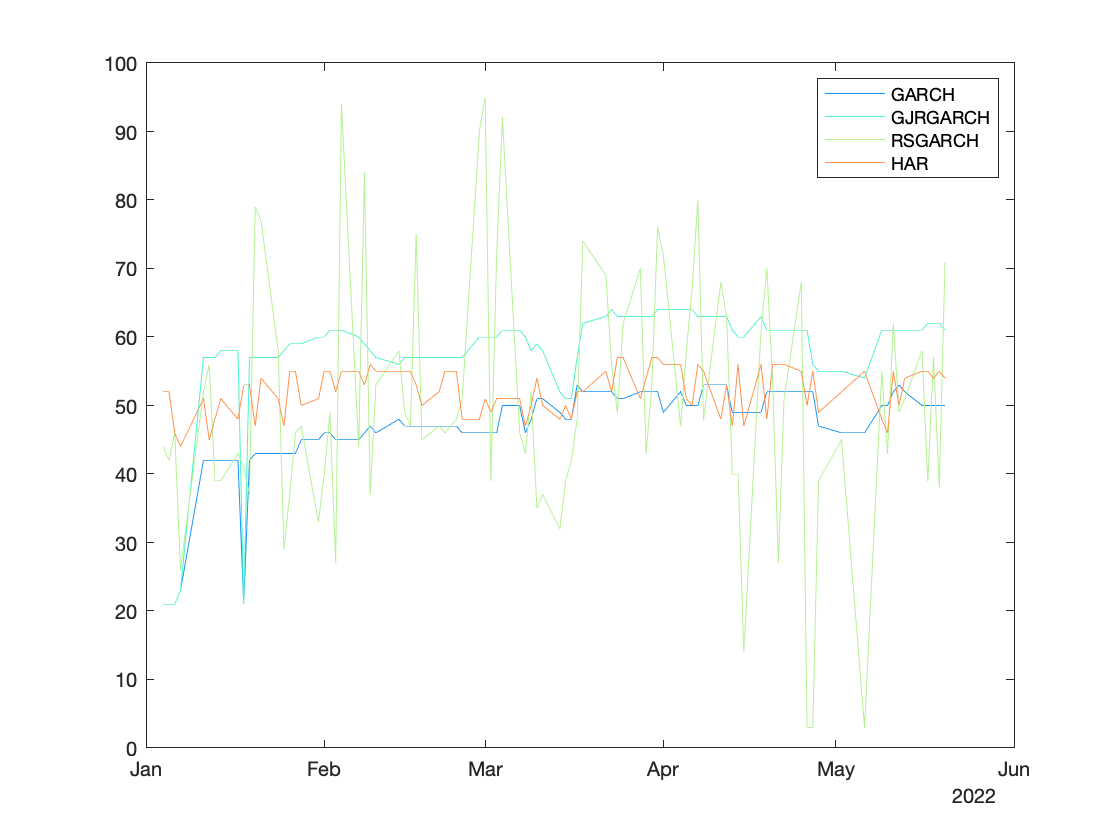

figure;
col=rainbow(4);
plot(Timeline_outsample,K_GARCH,"Color",col(1,:));hold on
plot(Timeline_outsample,K_GJRGARCH,"Color",col(2,:));hold on
plot(Timeline_outsample,K_RSGARCH,"Color",col(3,:));
plot(Timeline_outsample,K_HAR,"Color",col(4,:));
legend("GARCH","GJRGARCH","RSGARCH","HAR")

#### MAE & RMSE

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_RSGARCH-rv));mean(abs(vf_CPRSGARCH-rv));mean(abs(vf_CPRSGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_RSGARCH-rv).^2);mean((vf_CPRSGARCH-rv).^2);mean((vf_CPRSGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.',...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00012419    0.00014156
    CPGARCH            0.00011032    0.00015614
    GARCH Ite.         0.00012081    0.00014334
    GJRGARCH           0.00012924    0.00014734
    CPGJRGARCH         0.00012232    0.00017501
    CPGJRGARCH Ite.    0.00011806    0.00016479
    RSGARCH              0.020263      0.065169
    CPRSGARCH             0.27307        1.5057
    CPRSGARCH Ite.        0.31349        1.5363
    HAR                2.9852e-05     4.315e-05
    CPHAR              3.4088e-05    4.9298e-05
    HAR Ite.           3.4648e-05    5.0732e-05


#### MAE & RMSE without RSGARCH

MAE=[mean(abs(vf_GARCH-rv));mean(abs(vf_CPGARCH-rv));mean(abs(vf_CPGARCHiteration-rv))
    mean(abs(vf_GJRGARCH-rv));mean(abs(vf_CPGJRGARCH-rv));mean(abs(vf_CPGJRGARCHiteration-rv))
    mean(abs(vf_HAR-rv));mean(abs(vf_CPHAR-rv));mean(abs(vf_CPHARiteration-rv))];
RMSE=sqrt([mean((vf_GARCH-rv).^2);mean((vf_CPGARCH-rv).^2);mean((vf_CPGARCHiteration-rv).^2)
    mean((vf_GJRGARCH-rv).^2);mean((vf_CPGJRGARCH-rv).^2);mean((vf_CPGJRGARCHiteration-rv).^2)
    mean((vf_HAR-rv).^2);mean((vf_CPHAR-rv).^2);mean((vf_CPHARiteration-rv).^2)]);
table(MAE,RMSE,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 9×2 table
                          MAE           RMSE   
                       __________    __________

    GARCH              0.00012419    0.00014156
    CPGARCH            0.00011032    0.00015614
    GARCH Ite.         0.00012081    0.00014334
    GJRGARCH           0.00012924    0.00014734
    CPGJRGARCH         0.00012232    0.00017501
    CPGJRGARCH Ite.    0.00011806    0.00016479
    HAR                2.9852e-05     4.315e-05
    CPHAR              3.4088e-05    4.9298e-05
    HAR Ite.           3.4648e-05    5.0732e-05


DM test


table([normcdf(dmtest(vf_GARCH-rv,vf_CPGARCH-rv),0,1); normcdf(dmtest(vf_GARCH-rv,vf_CPGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_GJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPGJRGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_RSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCH-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPRSGARCHiteration-rv),0,1)
    normcdf(dmtest(vf_GARCH-rv,vf_HAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHAR-rv),0,1);normcdf(dmtest(vf_GARCH-rv,vf_CPHARiteration-rv),0,1)], ...
    'RowNames',{'CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.', ...
    'HAR','CPHAR','HAR Ite.'})

ans = 11×1 table
                         Var1   
                       _________

    CPGARCH              0.22961
    GARCH Ite.           0.43313
    GJRGARCH             0.22707
    CPGJRGARCH          0.057189
    CPGJRGARCH Ite.      0.12055
    RSGARCH            0.0038668
    CPRSGARCH            0.14804
    CPRSGARCH Ite.       0.13841
    HAR                        1
    CPHAR                      1
    HAR Ite.                   1


#### Test of actual forecast: 

actual_volatility = a + (b+1)*forecast_volatility

Null hypothesis: a=0, b+1=1

[~,bint_GARCH,~,~,stats_GARCH]=regress(rv,[ones(size(rv)) vf_GARCH]);
[~,bint_CPGARCH,~,~,stats_CPGARCH]=regress(rv,[ones(size(rv)) vf_CPGARCH]);
[~,bint_CPGARCHiteration,~,~,stats_CPGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGARCHiteration]);
[~,bint_GJRGARCH,~,~,stats_GJRGARCH]=regress(rv,[ones(size(rv)) vf_GJRGARCH]);
[~,bint_CPGJRGARCH,~,~,stats_CPGJRGARCH]=regress(rv,[ones(size(rv)) vf_CPGJRGARCH]);
[~,bint_CPGJRGARCHiteration,~,~,stats_CPGJRGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPGJRGARCHiteration]);
[~,bint_RSGARCH,~,~,stats_RSGARCH]=regress(rv,[ones(size(rv)) vf_RSGARCH]);
[~,bint_CPRSGARCH,~,~,stats_CPRSGARCH]=regress(rv,[ones(size(rv)) vf_CPRSGARCH]);
[~,bint_CPRSGARCHiteration,~,~,stats_CPRSGARCHiteration]=regress(rv,[ones(size(rv)) vf_CPRSGARCHiteration]);
[~,bint_HAR,~,~,stats_HAR]=regress(rv,[ones(size(rv)) vf_HAR]);
[~,bint_CPHAR,~,~,stats_CPHAR]=regress(rv,[ones(size(rv)) vf_CPHAR]);
[~,bint_CPHARiteration,~,~,stats_CPHARiteration]=regress(rv,[ones(size(rv)) vf_CPHARiteration]);
low_bound=[bint_GARCH(end,1);bint_CPGARCH(end,1);bint_CPGARCHiteration(end,1);
    bint_GJRGARCH(end,1);bint_CPGJRGARCH(end,1);bint_CPGJRGARCHiteration(end,1);
    bint_RSGARCH(end,1);bint_CPRSGARCH(end,1);bint_CPRSGARCHiteration(end,1)
    bint_HAR(end,1);bint_CPHAR(end,1);bint_CPHARiteration(end,1)];
upper_bound=[bint_GARCH(end,2);bint_CPGARCH(end,2);bint_CPGARCHiteration(end,2);
    bint_GJRGARCH(end,2);bint_CPGJRGARCH(end,2);bint_CPGJRGARCHiteration(end,2);
    bint_RSGARCH(end,2);bint_CPRSGARCH(end,2);bint_CPRSGARCHiteration(end,2)
    bint_HAR(end,2);bint_CPHAR(end,2);bint_CPHARiteration(end,2)];
R2=[stats_GARCH(1);stats_CPGARCH(1);stats_CPGARCHiteration(1);
    stats_GJRGARCH(1);stats_CPGJRGARCH(1);stats_CPGJRGARCHiteration(1);
    stats_RSGARCH(1);stats_CPRSGARCH(1);stats_CPRSGARCHiteration(1)
    stats_HAR(1);stats_CPHAR(1);stats_CPHARiteration(1)];
table(low_bound,upper_bound,R2,'RowNames',{'GARCH','CPGARCH','GARCH Ite.', ...
    'GJRGARCH','CPGJRGARCH','CPGJRGARCH Ite.', ...
    'RSGARCH','CPRSGARCH','CPRSGARCH Ite.','HAR','CPHAR','HAR Ite.'})

ans = 12×3 table
                        low_bound     upper_bound       R2    
                       ___________    ___________    _________

    GARCH                -0.018262       0.24902      0.032007
    CPGARCH              -0.035498       0.13128       0.01442
    GARCH Ite.             -0.1027       0.15636     0.0019002
    GJRGARCH               0.10306       0.32627       0.14098
    CPGJRGARCH            0.015016        0.1493      0.062284
    CPGJRGARCH Ite.     -0.0010656       0.14957      0.041332
    RSGARCH            -0.00018039    0.00012122     0.0017039
    CPRSGARCH          -2.7098e-06    9.8282e-06      0.014098
    CPRSGARCH Ite.      -1.432e-07    1.2034e-05      0.040582
    HAR            

#### Figure of volatility persistence

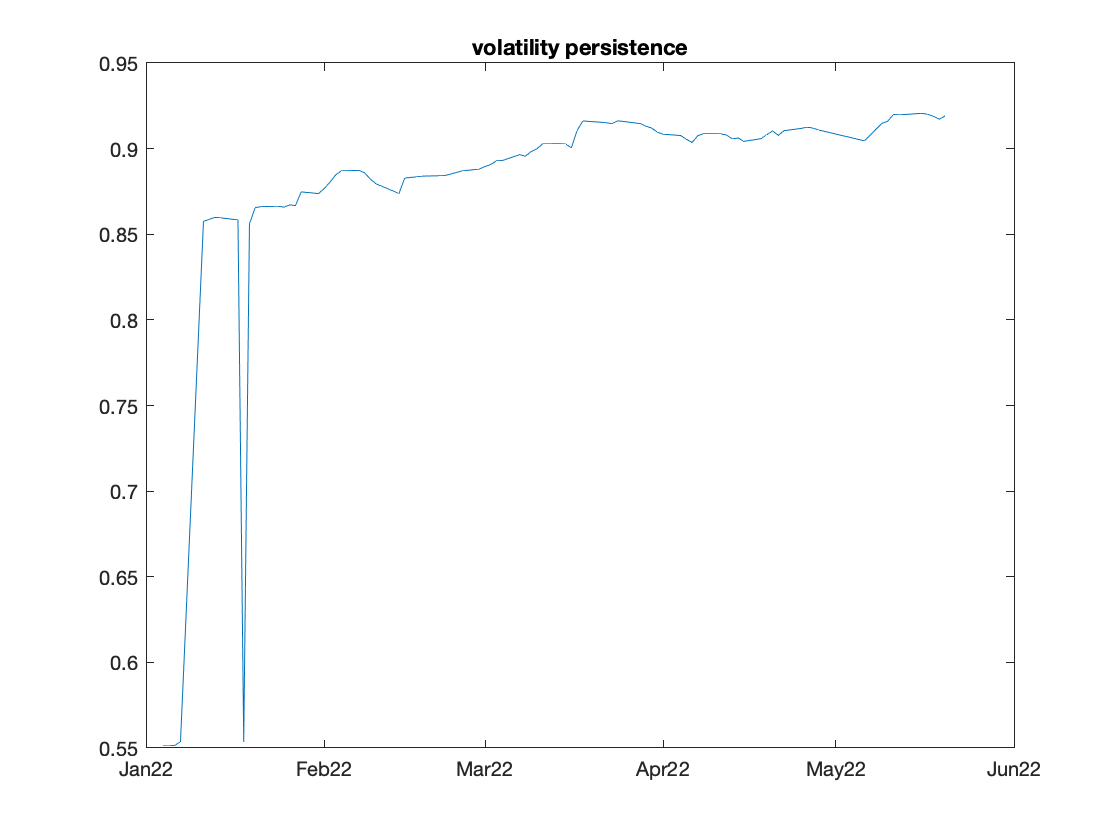

figure;
plot(Timeline_outsample,vol_persis);
dateaxis('x',12)
title("volatility persistence")

### save data

Ret_outsample=datatable.Return(I);
addpath("results_Files/")
save(strcat('results_Files/VolFcst_normal_',name,'_size1000_20220613'),"Timeline_outsample","Ret_outsample", ...
    "rv","vf_GARCH","vf_CPGARCH","vf_CPGARCHiteration", ...
    "vf_GJRGARCH","vf_CPGJRGARCH","vf_CPGJRGARCHiteration", ...
    "vf_RSGARCH","vf_CPRSGARCH","vf_CPRSGARCHiteration", ...
    "vf_HAR","vf_CPHAR","vf_CPHARiteration", ...
    "vol_persis", "K_GARCH","K_GJRGARCH","K_RSGARCH","K_HAR");


function [v_HAR,paras] = Vol_HAR(y,X)


x0=ones(size(y));
lm=fitlm(X,y);
paras=lm.Coefficients.Estimate;
v_HAR=exp([x0 X]*paras);

end

function DM = dmtest(e1, e2, h)
%DMTEST: Retrieves the Diebold-Mariano test statistic (1995) for the
% equality of forecast accuracy of two forecasts under general assumptions.
%
%   DM = dmtest(e1, e2, ...) calculates the D-M test statistic on the base
%   of the loss differential which is defined as the difference of the
%   squared forecast errors
%
%   In particular, with the DM statistic one can test the null hypothesis:
%   H0: E(d) = 0. The Diebold-Mariano test assumes that the loss
%   differential process 'd' is stationary and defines the statistic as:
%   DM = mean(d) / sqrt[ (1/T) * VAR(d) ]  ~ N(0,1),
%   where VAR(d) is an estimate of the unconditional variance of 'd'.
%
%   This function also corrects for the autocorrelation that multi-period
%   forecast errors usually exhibit. Note that an efficient h-period
%   forecast will have forecast errors following MA(h-1) processes.
%   Diebold-Mariano use a Newey-West type estimator for sample variance of
%   the loss differential to account for this concern.
%
%   'e1' is a 'T1-by-1' vector of the forecast errors from the first model
%   'e2' is a 'T2-by-1' vector of the forecast errors from the second model
%
%   It should hold that T1 = T2 = T.
%
%   DM = DMTEST(e1, e2, 'h') allows you to specify an additional parameter
%   value 'h' to account for the autocorrelation in the loss differential
%   for multi-period ahead forecasts.
%       'h'         the forecast horizon, initially set equal to 1
%
%   DM = DMTEST(...) returns a constant:
%       'DM'      the Diebold-Mariano (1995) test statistic
%
%  Semin Ibisevic (2011)
%  $Date: 11/29/2011 $
%
% -------------------------------------------------------------------------
% References
% K. Bouman. Quantitative methods in international finance and
% macroeconomics. Econometric Institute, 2011. Lecture FEM21004-11.
%
% Diebold, F.X. and R.S. Mariano (1995), "Comparing predictive accuracy",
% Journal of Business & Economic Statistics, 13, 253-263.
% -------------------------------------------------------------------------

if nargin < 2
    error('dmtest:TooFewInputs','At least two arguments are required');
end
if nargin < 3
    h = 1;
end
if size(e1,1) ~= size(e2,1) || size(e1,2) ~= size(e2,2)
    error('dmtest:InvalidInput','Vectors should be of equal length');
end
if size(e1,2) > 1 || size(e2,2) > 1
    error('dmtest:InvalidInput','Input should have T rows and 1 column');
end

% Initialization
T = size(e1,1);

% Define the loss differential
d = e1.^2 - e2.^2;

dMean = mean(d);
gamma0 = var(d);
if h > 1
    gamma = zeros(h-1,1);
    for i = 1:h-1
        gamma(i) = ( d(1+i:T)' * d(1:T-i) ) ./ T; % bugfix
    end
    varD = gamma0 + 2*sum(gamma);
else
    varD = gamma0;
end

DM = dMean / sqrt ( (1/T)*varD );
end